**depends on variables in "qualsis_experiment" and "uav_data_process"**

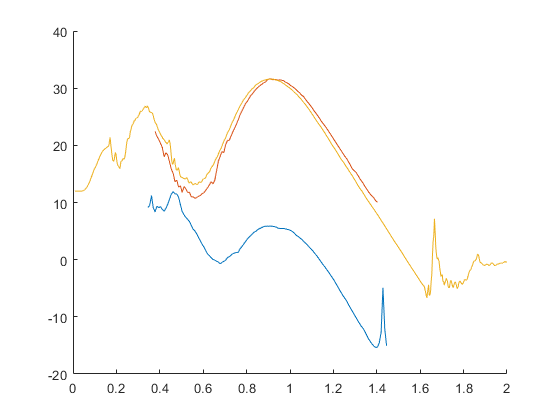

% line up accelerations and glide angle in time
qualsis_time_offset = 7.48;
clf
hold on
plot(qualsis_time-qualsis_time_offset, glideAngle)
plot(qualsis_time-qualsis_time_offset, pitch)
plot(uav_data(:,1)/1e6,orientation(:,1))
hold off

rebase_time = @(x,f) 0.001:0.001:1/f*length(x);

%rebase qualsis data
rebase_qualsis = @(x) rmmissing(interp1(1/120:1/120:(1/120*length(rmmissing(x))), rmmissing(x), rebase_time(x,120)));
rebase_uav = @(x) rmmissing(interp1(uav_data(:,1)./1e6, x, rebase_time(x,333)));

new_glide_angle = rebase_qualsis(glideAngle);
new_AoA = rebase_qualsis(angleOfAttack);
new_qualsis_v = rebase_qualsis(qualsis_v);
new_pitch = rebase_qualsis(pitch);

uav_pitch = rebase_uav(orientation(:,1));
new_ax = rebase_uav(ax);
new_ay = rebase_uav(ay);
new_az = rebase_uav(az);

[correlate, lags] = xcov(uav_pitch, new_pitch);
[corr_m,corr_i] = max(correlate)

corr_m = 4.9575e+04

corr_i = 2351

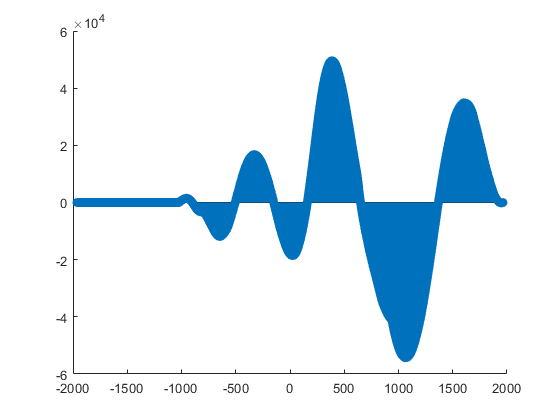

stem(lags, correlate)

shift =-30

shift = -30

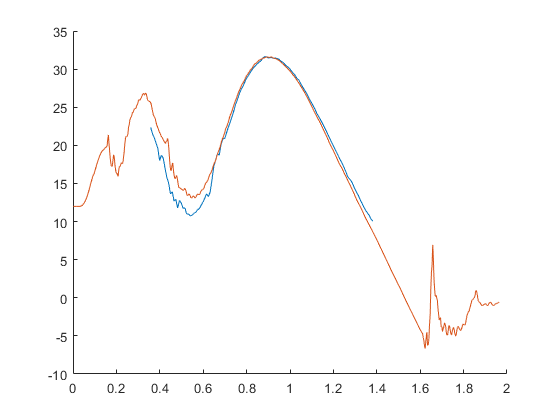

clf
hold on
new_pitch_padded = [NaN(1, corr_i - length(uav_pitch) + shift), new_pitch];
plot(rebase_time(new_pitch_padded,1000), new_pitch_padded);
plot(rebase_time(uav_pitch,1000), uav_pitch);
hold off

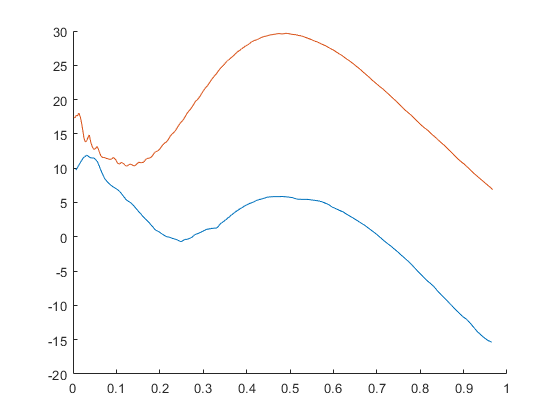

qualsis_index_trim = 950;
uav_index_trim = 140;

qualsis_index_trim_end = 1065;
uav_index_trim_end = 457;

overall_offset = 0.43;

clf
hold on
plot(qualsis_time(qualsis_index_trim:qualsis_index_trim_end)-qualsis_time_offset-overall_offset, glideAngle(qualsis_index_trim:qualsis_index_trim_end))
plot(uav_data(uav_index_trim:uav_index_trim_end,1)/1e6-overall_offset,orientation(uav_index_trim:uav_index_trim_end,1))
hold off

qualsis_time_adj = qualsis_time(qualsis_index_trim:qualsis_index_trim_end)-qualsis_time_offset-overall_offset;
uav_time_adj = uav_data(uav_index_trim:uav_index_trim_end,1)/1e6-overall_offset;

glide_angle_trim = glideAngle(qualsis_index_trim:qualsis_index_trim_end);
AoA_trim = angleOfAttack(qualsis_index_trim:qualsis_index_trim_end);
V_trim = qualsis_v(qualsis_index_trim:qualsis_index_trim_end);

ax_trim = ax(uav_index_trim:uav_index_trim_end,1);
ay_trim = ay(uav_index_trim:uav_index_trim_end,1);
az_trim = az(uav_index_trim:uav_index_trim_end,1);

new_time = 0:0.001:0.9;

glide_angle_adj = interp1(qualsis_time_adj, glide_angle_trim, new_time);
AoA = interp1(qualsis_time_adj, AoA_trim, new_time);
V_adj = interp1(qualsis_time_adj, V_trim, new_time);
ax_adj = interp1(uav_time_adj, ax_trim, new_time);
ay_adj = interp1(uav_time_adj, ay_trim, new_time);
az_adj = interp1(uav_time_adj, az_trim, new_time);

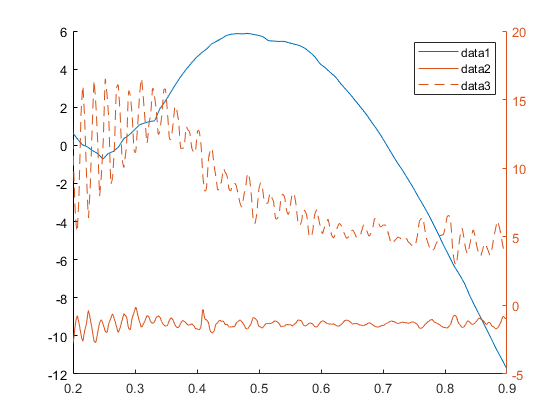

clf
hold on
xlim([0.2,0.9])
plot(new_time, glide_angle_adj)
yyaxis right
plot(new_time, ax_adj)
plot(new_time, ay_adj)
hold off
legend

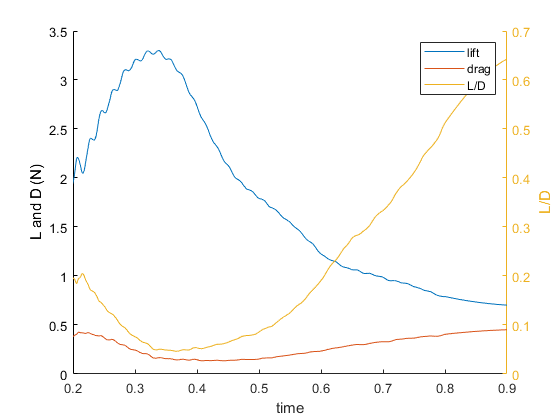

% correct acclerations to glide angle
a_x = (ay_adj.*cosd(glide_angle_adj) + ax_adj)./(cosd(glide_angle_adj).*cosd(glide_angle_adj)-sind(glide_angle_adj));
a_y = (ax_adj + a_x.*sind(glide_angle_adj))./cosd(glide_angle_adj);

lift = smooth(new_time, a_x, 200, 'sgolay')*0.25;
drag = smooth(new_time, abs(a_y), 200, 'sgolay')*0.25;

clf
hold on
xlim([0.2,0.9])
plot(new_time, lift, 'DisplayName', "lift")
plot(new_time, drag, 'DisplayName', "drag")
ylabel("L and D (N)")
yyaxis right
ylabel("L/D")
plot(new_time, abs(drag)./abs(lift), 'DisplayName', "L/D")
hold off
legend
xlabel("time")

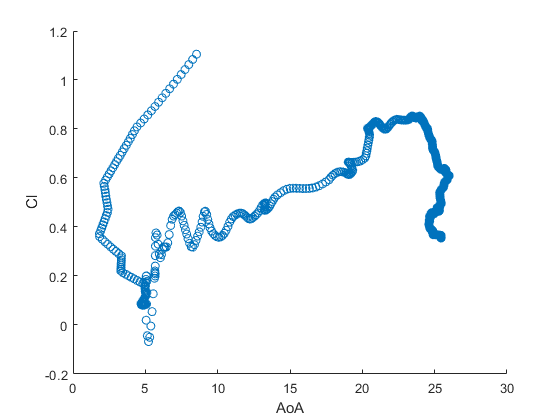

V_adj_smooth = smooth(new_time, V_adj, 50, 'sgolay');
A = 0.15*0.8;
Cl = (2.*lift)./(1.225.*V_adj_smooth.^2.*A);
clf
scatter(AoA, Cl)
xlabel("AoA")
ylabel("Cl")